
clc;
clear;
[~,sheet_name_Ar]=xlsfinfo('gait_test_15cmps.csv');

Error using validpath>getFullName
File 'C:\Users\Jahnav Rokalaboina\Dropbox (ASU)\Exosuit & RL Project\online_RL_v2\gait_test_15cmps.csv' not found.

Error in validpath (line 23)
        filenameOut = getFullName(filename);

Error in xlsfinfo (line 48)
    filename = validpath(

for k=1:numel(sheet_name_Ar)
  Gait{k}=xlsread('gait_test_15cmps.csv',sheet_name_Ar{k});
end

grf = Gait{1,1}(:,2);
timestamp = Gait{1,1}(:,5);

grf = grf(252:23436);
timestamp = timestamp(252:23436);
plot(timestamp,grf)


J = grf>15;



timestamp = timestamp*1000;

j=1;
for i=1:length(J)-1
    if ((J(i+1)-J(i))>0)
        Index_Cycle_Vicon(j)=i;
        j=j+1;
    end
    i=i+1;
  
end

for p=1:length(Index_Cycle_Vicon)-1
    ind_Vicon(p,1)=Index_Cycle_Vicon(p);
    ind_Vicon(p,2)=Index_Cycle_Vicon(p+1);
end



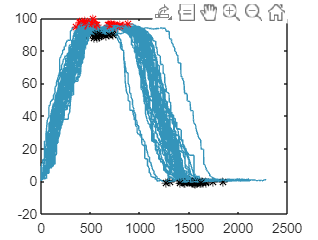


ind_Vicon = ind_Vicon((ind_Vicon(:,2)-ind_Vicon(:,1))>300,:);
figure;
grf = 100*(grf./max(grf));
ff_time = 0;
ho_time = 0;
ms_time = 0;
to_time = 0;
p1 = 1;
p2 = 1;
p3 = 1;
for i=1:length(ind_Vicon)
    timevec = timestamp(ind_Vicon(i,1):ind_Vicon(i,2))-timestamp(ind_Vicon(i,1));
    grfvec = grf(ind_Vicon(i,1):ind_Vicon(i,2));
    grfvechalf = grfvec(round(length(grfvec)/2):end);
    timevechalf = timevec(round(length(grfvec)/2):end);
    TF = islocalmax(grfvec,'MinProminence',5);
    BF = islocalmin(grfvec,'MinProminence',4);
    BF1 = islocalmin(grfvechalf,'MinProminence',1);
    plot(timevec,grfvec,"color",[ 52 148 186]./255)
    hold on
    plot(timevec(TF),grfvec(TF),'r*');
    hold on
    plot(timevec(BF),grfvec(BF),'k*');
    hold on
    plot(timevechalf(BF1),grfvechalf(BF1),'k*');
    hold on

    temp_timevec = timevec(TF);    
    if length(temp_timevec)==2
        ff_time = ff_time+temp_timevec(1);
        ho_time = ho_time+temp_timevec(2);
        p1=p1+1;
    end

    temp_timevec = timevec(BF);    
    if length(temp_timevec)==1
        ms_time = ms_time+temp_timevec(1);
        p2=p2+1;
    end

    temp_timevec = timevechalf(BF1);    
    if length(temp_timevec)==1
        to_time = to_time+temp_timevec(1);
        p3=p3+1;
    end

    i=i+1;
end



disp(['Foot Flat Time: ',num2str(ff_time/p1)])

Foot Flat Time: 434.8501


disp(['Mid Stance Time: ',num2str(ms_time/p2)])

Mid Stance Time: 581.8581


disp(['Heel Off Time: ',num2str(ho_time/p1)])

Heel Off Time: 698.0765


disp(['Toe Off Time: ',num2str(to_time/p3)])

Toe Off Time: 1511.602


% xlabel("Arbitrary")
% ylabel("Force (N)")
% set(gca,'fontname','times')  % Set it to times
% set(gca,"FontSize",14)
% title("Raw Gait Cycle Snipptes (Vicon)- Subject 3,25 psi @ 0.75m/s")
% grid on
% hold off

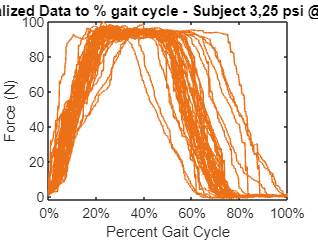

figure;
for i=1:length(ind_Vicon)
    vector_to_normalize_1 = grf(ind_Vicon(i,1):ind_Vicon(i,2));  %this is the data vector to normalize (e.g. kinematics, grfs)
    temp = 1:length(vector_to_normalize_1);
    x = 100*(temp - min(temp)) / ( max(temp) - min(temp) );
    pgc = linspace(0,100,1001);  %resample at 1001 data points (each data point is 0.1 gait cycle at this scale). Using 1001 points for better plot resolution.
    vector_normalized_1 = spline(x,vector_to_normalize_1,pgc); 
    ViconGait(i,:)=vector_normalized_1;
    plot(pgc,vector_normalized_1,"color",[236 112  22]./255)
    i=i+1;
    hold on
end

title('Normalized Data to % gait cycle - Subject 3,25 psi @ 0.75m/s')
xlabel('Percent Gait Cycle'); xtickformat('percentage')
ylabel('Force (N)')
hold off

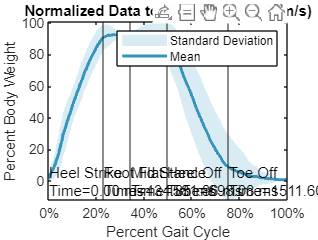

figure;
options.color_area = [128 193 219]./255;    % Blue theme
options.color_line = [ 52 148 186]./255;
options.error      = 'std';
options.handle     = figure(1);
options.alpha      = 0.3;
options.line_width = 2;
plot_areaerrorbar(ViconGait,options)
hold on

text(0.05,0,sprintf('Heel Strike \nTime=%4.2f ms',0))

xline(23);
text(23.05,0,sprintf('Foot Flat \nTime=%4.2f ms',ff_time/p1))
xline(34.5);
text(34.55,0,sprintf('Mid Stance \nTime=%4.2f ms',ms_time/p2))

xline(49.7);
text(49.75,0,sprintf('Heel Off \nTime=%4.2f ms',ho_time/p1))

xline(75.3);
text(75.35,0,sprintf('Toe Off \nTime=%4.2f ms',to_time/p3))

hold off
legend("Standard Deviation","Mean")
title('Normalized Data to % gait cycle 0.25m/s)')
xlabel('Percent Gait Cycle'); xtickformat('percentage')
ylabel('Percent Body Weight')

function plot_areaerrorbar(data, options)
    % Default options
    if(nargin<2)
        options.handle     = figure(1);
        options.color_area = [128 193 219]./255;    % Blue theme
        options.color_line = [ 52 148 186]./255;
        %options.color_area = [243 169 114]./255;    % Orange theme
        %options.color_line = [236 112  22]./255;
        options.alpha      = 0.5;
        options.line_width = 2;
        options.error      = 'std';
    end
    if(isfield(options,'x_axis')==0), options.x_axis = linspace(0,100,1001); end
    options.x_axis = options.x_axis(:);
    
    % Computing the mean and standard deviation of the data matrix
    data_mean = mean(data,1);
    data_std  = std(data);
    
    % Type of error plot
    switch(options.error)
        case 'std', error = data_std;
        case 'sem', error = (data_std./sqrt(size(data,1)));
        case 'var', error = (data_std.^2);
        case 'c95', error = (data_std./sqrt(size(data,1))).*1.96;
    end
    
    % Plotting the result
    figure(options.handle);
    x_vector = [options.x_axis', fliplr(options.x_axis')];
    patch = fill(x_vector, [data_mean+error,fliplr(data_mean-error)], options.color_area);
    set(patch, 'edgecolor', 'none');
    set(patch, 'FaceAlpha', options.alpha);
    hold on;
    plot(options.x_axis, data_mean, 'color', options.color_line, ...
        'LineWidth', options.line_width);
 
    hold on
end
